# [Soil Classification using Deep Learning](https://apmonitor.com/pds/index.php/Main/SoilClassification)

Classification of soils can be an important capability in many fields including geotechnical engineering, agricultural science, and construction. While many classification schemes exist, a popular and intuitive way of classifying soils is based on soil grain size, such as gravel, silt, sand, etc. This is a rather simple way of classifying soil because there are firm cutoffs between each classification. For example, gravel is any grain over 2 mm in diameter, sand is between 116 mm to 2 mm, and silt/clay is smaller than 116 mm. See [additional information on soil classification](https://apmonitor.com/pds/index.php/Main/SoilClassification).

Deep Learning (DL) is a subset of Machine Learning that uses Neural Network inspired architecture to make predictions. Convolutional Neural Networks (CNN) are a type of DL model that is effective in learning patterns in 2-dimensional data such as images. Images of soils are used to train a classifier to identify common soil types and fractions of soil type.

This exercise demonstrates the use of image classification to distinguish between soil types. Although applied to soil, the same methods and code can be used for any type or number of items. This example can be modified by including train and test photos in folders that are named with the item type. The code automatically takes the name of the folder as the photo label for training the classifier. Additional examples of image-based CNNs are found in the [Bit and Crack Classification Case Study](https://apmonitor.com/pds/index.php/Main/BitClassification).

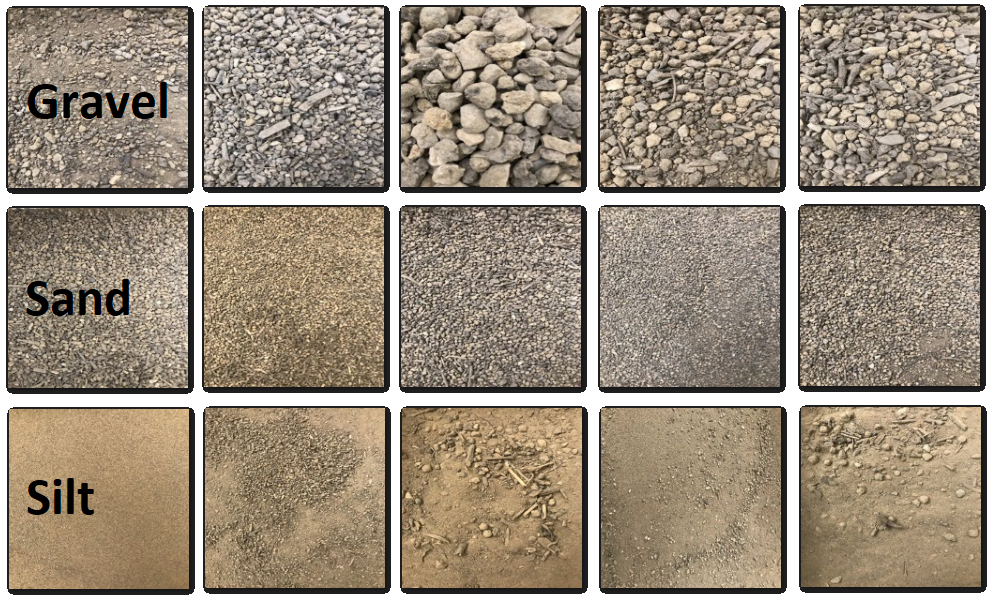

The archive contains two folders, a test folder and train folder with subdirectories corresponding to the possible soil types (Gravel, Sand, and Silt). The images are found within each subdirectory. The tree structure of the folders is:

`  ├───test`

`  │   ├───Gravel`

`  │   ├───Sand`

`  │   └───Silt`

`  └───train`

`      ├───Gravel`

`      ├───Sand`

`      └───Silt`

**Objective**

In this exercise, computer vision makes a classification model of soils based on photos of gravel, sand, and silt. A convolutional neural network framework is used classify photos of soil.

**Key Concepts:Data Augmentation**

Data Augmentation is a practice that is commonly used in image classification that enlarges the existing image dataset by creating new data sets from the existing data. This augmentation is most commonly seen in operations like shifting the image, mirroring the image horizontally or vertically, zooming in on the image, and so on. These augmentations then create new images and thus enhance the number of images to train on. Read more about this in an [article from Jason Brownlee](https://machinelearningmastery.com/how-to-configure-image-data-augmentation-when-training-deep-learning-neural-networks/).

**Convolutional Neural Network (CNN)**

A convolutional neural network (CNN) is a popular model for image classification. CNNs distinguish characteristics of an image by looping through the pixel values in an image and calculating the dot product of a those pixels with a filter `kernel` matrix. These kernel matrices accentuate different aspects of the image such as vertical and horizontal lines, curvature, etc. For more information on CNNs, see [APMonitor - Computer Vision with Deep Learning](https://apmonitor.com/pds/index.php/Main/VisionDeepLearning).

training_data_directory = 'train';
test_data_directory = 'test';

**Data**

The data is separated into directories test and train. The test folder and train folder contain subdirectories corresponding to the possible soils. The labeled tree structure of the folders assists with marking the photos for training and testing.

% Download the file
url = 'http://apmonitor.com/pds/uploads/Main/soil_photos.zip';
filename = 'soil_photos.zip';
outfilename = websave(filename,url);

% Unzip then deleate zip folder
unziped_folder = unzip(filename);
delete(filename);

Import the data into the MATLAB live editor. The first step is to process the images into a format that 1) makes the data readable to the model, and 2) provides more training material for the model to learn from. Neural networks import inputs with different sizes. Therefore the images need to be rescaeld to a certain size, in this case [255,255] to be processed.

% Create data augmentation settings
augmenter = imageDataAugmenter(...
    'RandRotation',[-15,15], ...
    'RandXScale',[0.8,1.2], ...
    'RandYScale',[0.8,1.2], ...
    'RandXTranslation',[-20,20], ...
    'RandYTranslation',[-20,20], ...
    'RandXReflection', true);

% Load training data
train = imageDatastore(['train',filesep], 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
train_preprocess = augmentedImageDatastore([255,255],train, "DataAugmentation",augmenter);

% Load testing data
test = imageDatastore(['test',filesep], 'IncludeSubfolders',true, ...
    'LabelSource','foldernames','ReadFcn',@imread);
test = augmentedImageDatastore([255,255],test,"DataAugmentation", augmenter);

## Model Building

Build the CNN model. The following cell sets parameters for model building. This includes the number of convolutional layers, fully connected dense layers, the number of nodes in each layer, and the number of training epochs. For more information on these parameters and Convolutional Neural Networks in general, see [APMonitor - Computer Vision with Deep Learning](https://apmonitor.com/pds/index.php/Main/VisionDeepLearning). The `layer_size` parameter has a large influence on the training speed, accuracy, and size of the model.

The following code will change the size of the different layers. Where num_conv_layers is the number of 2d convolution layers, num_dense_layers is the number of fully connected layers, the layer_size affects the size of the fully connected layers, and the num_training_epochs is the number of epochs the neural network will perform.

num_conv_layers = 1;
layer_size = 20;
num_training_epochs = 20;

**Build the CNN model**

The code below was created using the Deep Network Designer and then modified to include the inputs above. This can be built through the builtin-app "[Deep Network Designer](https://www.mathworks.com/help/deeplearning/gs/get-started-with-deep-network-designer.html)"

% Preallocate the layers array as a cell array
layers = cell((num_conv_layers+1)*3 + 1, 1);

layers{1} = imageInputLayer([255 255 3]); 
layers{2} = convolution2dLayer([3 3],layer_size);
layers{3} = reluLayer();
lyaers{4} = maxPooling2dLayer([2 2]);

% Add additional convolutional layers based on num_conv_layers
for i = 1:num_conv_layers-1
    layers{i*3 + 2} = convolution2dLayer([3 3],layer_size);
    layers{i*3 + 3} = reluLayer();
    layers{i*3 + 4} = maxPooling2dLayer([2 2]);
end

layers{end - 2} = fullyConnectedLayer(3);
layers{end - 1} = softmaxLayer();
layers{end} = classificationLayer();

% Convert layers into an array
layers = [layers{:}];

options = trainingOptions("adam", ...
    InitialLearnRate=0.01, ...
    SquaredGradientDecayFactor=0.99, ...
    MaxEpochs=num_training_epochs, ...
    MiniBatchSize=32, ...
    Verbose=true,...
    ValidationData=test);

**Build the CNN model with the Deep Network Designer**

Open the Deep Network Designer under the Apps in the ribbon.

When the pop-up comes up, click New on the Blank Network. The following window will appear. 

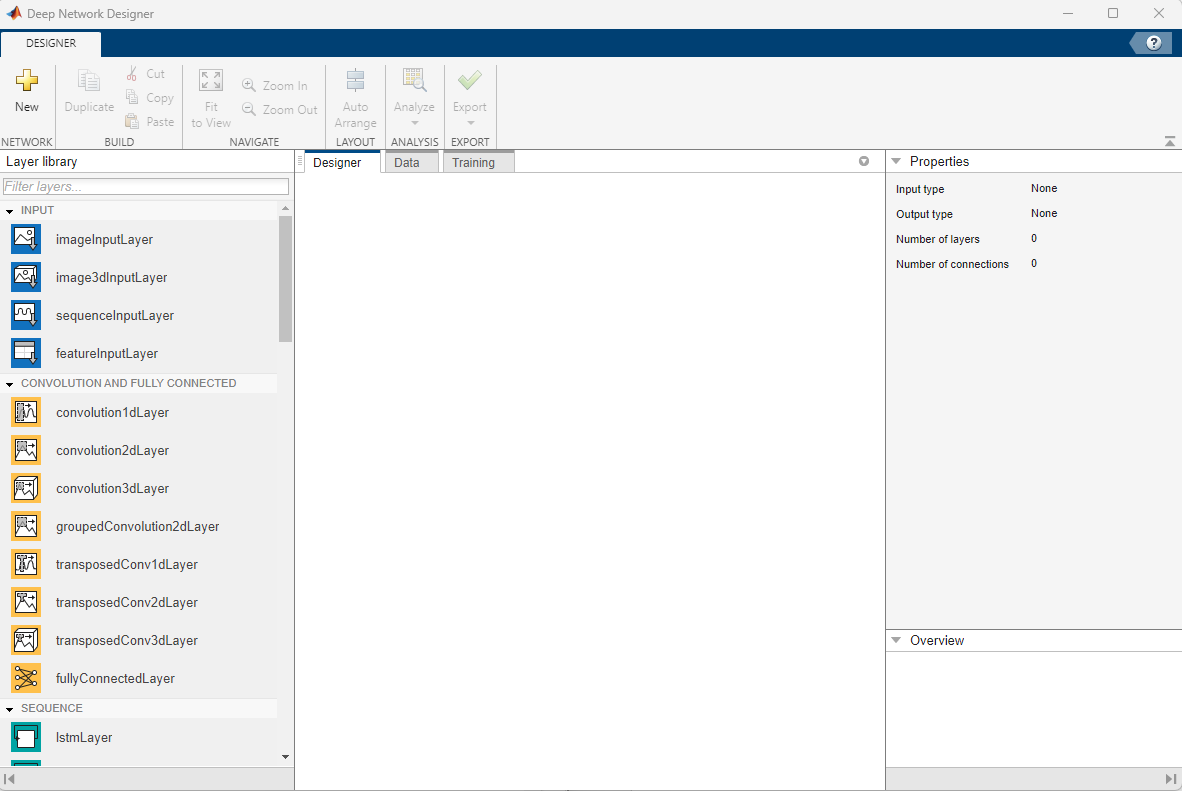

Next, you can drag and drop the layers from the left hand side to the Designer tab. Once all layers on set in the Designer tab, link the layers in order with the arrows. You can change the number of layers to your desire (remember the more layers in your neural network, the more computing power required). The picture below is the example network made above.

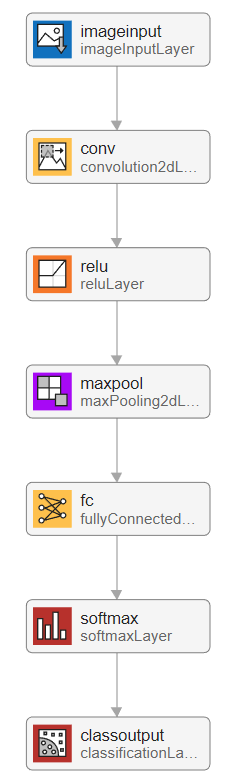

To copy the neural network that is above, ensure to input the following changes to the default properties.

**imageInputLayer**

InputSize: 255,255,3

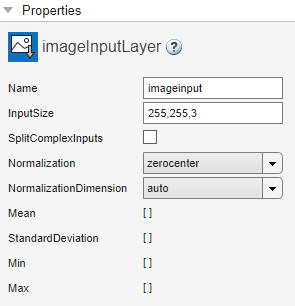

**convolution2dLayer**

FilterSize: 3,3

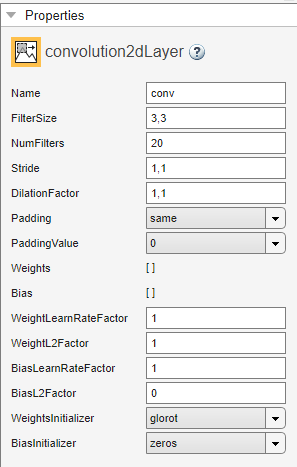

**maxPooling2dLayer**

PoolSize: 2,2

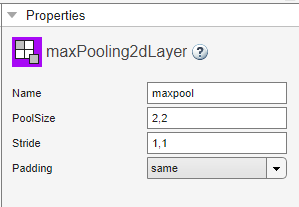

**fullyConnectedLayer**

outputSize: 3

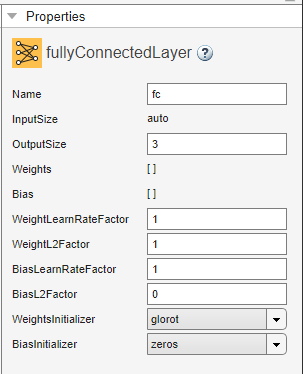

Further details are offered in [Introduction to Convolutional Neural Networks](https://www.mathworks.com/help/deeplearning/ug/introduction-to-convolutional-neural-networks.html)

**Train Neural Network**

[net,~] = trainNetwork(train_preprocess, layers, options);

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |       18.75% |       33.33% |      21.3081 |   43853.8047 |          0.0100 |
|      20 |          40 |       00:00:38 |       96.88% |       86.67% |     344.0383 |    2673.6958 |          0.0100 |
|======================================================================================================================|
Training finished: Max epochs completed.


**Train Neural Network with the Deep Network Designer**

Click on the Data tab and click Import Data in the top left. 

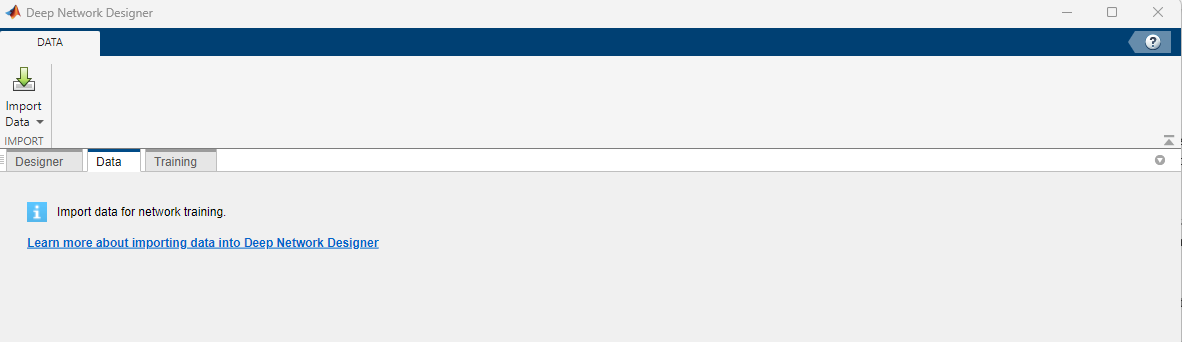

Click Import Custom Data. On the pop-up, select train_preprocess - augmentedImageDataStore for the training data and click test for the Validation data. 

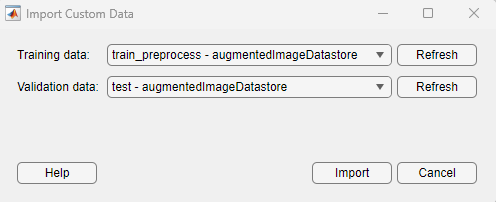

Import. Now click on the training tab and click Training Options in the top left. Change the Number of Epochs to 20 and click ok. 

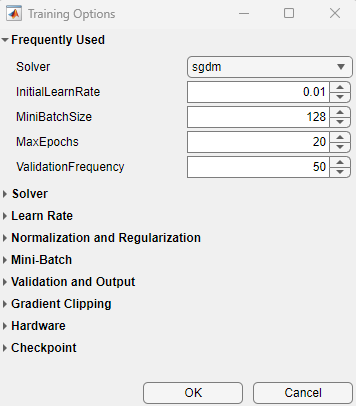

Now click Train. After the network is trained you can click the export button to either generate the code for your neural network or export the trained neural network. 

## `Model Testing`

The model has now been trained and has been saved within the script.

The following function code takes the file path to a soil photo as an input and outputs the classification that the model predicted. Try out a few photos and see how the model preforms. Run the code below a few times to see how it works!

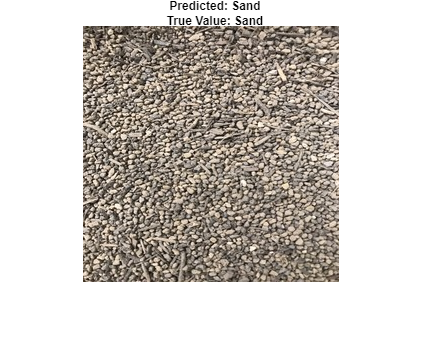

btype = ["Gravel", "Sand", "Silt"]; % possible output values
rng('shuffle');
i=randi(3);
j=randi([0,5]);
b = btype(i);

% There are a few images that are missing in the test files, so this is to
% avoid any errors that may occur by trying to call a image that doesn't exist
if i == 1 && j == 3
    j = j+1;
elseif i == 2 && j == 3
    j = j + 1;
elseif i == 3 && j == 4
    j = j + 1;
end

% Get the image file path
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',""))); 
image_fp = fullfile('./test',b,im);

% Read the image
ime = imread(image_fp);

% Make a prediction
im = double(imresize(ime,[255 255]));
predicted_value = net.classify(im);
text_pre = "Predicted: " + string(predicted_value);

% Get the true value
true_value = regexp(image_fp, "(Gravel)|(Sand)|(Silt)", 'match');
true_value = true_value{1};
text_tru = "True Value: " + string(true_value);

% Display the image with the prediction and the true value
imshow(ime);
title_text = sprintf("%s\n%s", text_pre, text_tru);
title_conf = title(title_text, 'FontSize', 9);
set(title_conf, "Position", get(title_conf, 'Position')+4);

## Soil Classification Percentages

Soils are not perfectly homogenous (all one soil type). Soils are often a blend of types and may be better represented using a percentage. For example, the cell below shows a test photo that is labeled "Silt":

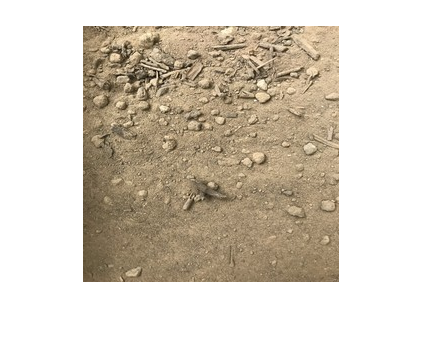

% Pick an image
j = 5;
b = "Silt";
im = strcat(lower(strrep(strcat(num2str(j),'.jpg'),'',"")));
test_image_filepath = fullfile('./test',b,im);

% Read and display the image
image_fp = test_image_filepath;
ime = imread(image_fp);
imshow(ime)

This photo has some gravel, however, there appears to be sand, gravel, and silt all in one photo. In order to better classify this image, create a proportion of each label. For example, this photo might be 30% Gravel, 20% Sand, and 50% Silt.

Subdivide the photo into many smaller segments or squares and train a classifier on the smaller squares. Loop through the photo to classify each small square and take a proportion of the squares pertaining to Gravel, Sand, and Silt. This proportion is then converted into a percentage of the respective soil type.

**Data**

Run these cells below to subdivide the existing training photos into smaller segments. The new directory will be called train_divided and test_divided.

Note: This will take time (~30 seconds to 2 minutes)

parent = strrep(training_data_directory, 'train', '');
dirs = {'train_divided', 'test_divided'};
class_ = ["Gravel", "Sand", "Silt"];

for i = 1:numel(dirs)
    dir_ = dirs{i};
    if ~exist(fullfile(parent, dir_), "dir")
        mkdir(fullfile(parent, dir_));
    end
    for j = 1:numel(class_)
        classification = class_{j};
        if ~exist(fullfile(parent, dir_, classification), 'dir')
            mkdir(fullfile(parent, dir_, classification));
        end
    end
end

split_image(training_data_directory, strrep(training_data_directory, 'train', 'train_divided'))
split_image(test_data_directory, strrep(test_data_directory, 'test', 'test_divided'))

**Load Model**

If the number of input pixels changes, a new model should be trained or the image rescaled to the original training dimensions. For the purposes of this demo, retraining is not needed because the photos are upscaled to 1024x1024 before subsampling 256x256 blocks (16) in each image.

**Classify Image**

Use the loaded model to classify a test image. The functions below take an image and a model and loops through each 256x256 square. It classifies each square and adds to the counter to create the fractional soil prediction. The function outputs the proportion of each soil type that was classified.

start = tic; % Start a timer
classes = {'Gravel', 'Sand', 'Silt'}; % Define the classes

% Create variables to store the number of each classification
gravel_count = 0;
sand_count = 0;
silt_count = 0;

% Read the image and expand its size
img = imread(image_fp);
img = imresize(img, [1024, 1024]);
im_dim = 256;

% Loop through each segments of the photo in sizes of 256
for r = 1:im_dim:size(img, 1)
    for c = 1:im_dim:size(img, 2)
        % Get the cropped image
        cropped_img = img(r:r+im_dim-2, c:c+im_dim-2, :);

        % Get the height and width of the cropped image
        [h, w, ~] = size(cropped_img);

        % Classify the cropped image and store the prediction
        if h == im_dim-1 && w == im_dim-1
            % Classify the prediction
            classes = ["Gravel", "Sand", "Silt"];
            prediction = net.classify(cropped_img);
            classification = string(prediction);

            % Store the prediction
            if strcmp(classification, classes{1})
                gravel_count = gravel_count + 1;
            elseif strcmp(classification, classes{2})
                sand_count = sand_count + 1;
            elseif strcmp(classification, classes{3})
                silt_count = silt_count + 1;
            end
        else
            continue
        end
    end
end

% End the timer
finish = round(toc(start), 5);

% Read and display the image
im = imread(image_fp);
imshow(im(:,:,[1 2 3]));

total_count = gravel_count + sand_count + silt_count;
fprintf("Percent Gravel: %.2f%%\n", gravel_count/total_count*100);

Percent Gravel: 18.75%


fprintf("Percent Sand: %.2f%%\n", sand_count/total_count*100);

Percent Sand: 0.00%


fprintf("Percent Silt: %.2f%%\n", silt_count/total_count*100);

Percent Silt: 81.25%


fprintf("Time to Classify: %.5f seconds\n", finish);

Time to Classify: 0.32306 seconds


**Supporting Functions**

function split_image(image_dir,save_dir)
    classification_list = {'Gravel', 'Sand', 'Silt'};
    for i=1:numel(classification_list)
        classification = classification_list{i};
        folder = [image_dir '/' classification '/'];
        save_folder = [save_dir '/' classification '/'];
        files = dir([folder '*.jpg']);
        for j=1:numel(files)
            file = files(j).name;
            if contains(file, '.ini')
                continue;
            end
            fp = [folder file];
            img = imread(fp);
            [h, w, ~] = size(img);
            im_dim = 64;
            for r = 1:im_dim:h
                for c = 1:im_dim:w
                    cropped_img = img(r:r+im_dim-1, c:c+im_dim-1, :);
                    [ch, cw, ~] = size(cropped_img);
                    if ch == im_dim && cw == im_dim
                        write_path = [save_folder num2str(randi(100000)) 'img' num2str(r) '_' num2str(c) '.jpg'];
                        imwrite(cropped_img, write_path);
                    end
                end
            end
        end
    end
end

**Does the percentage classified match the photo?**

Both approaches to soil classification have advantages. For example, classifying the entire image is faster. However, percentage classification is more computationally expensive but provides more information and may be a better representation of the true classification.